# Aula Prática 2

## Plot com matlab

### Plotando em duas dimensões

a)plot a função $y\left(x\right)=x^2 ,-2\le x\le 2$

clear all; close all
clc
x =-2:2

x =     -2    -1     0     1     2


length(x)

ans = 5

% o x e um vetor então todos elemento do x vão ser ao quadrado 
y = x.^2

y =      4     1     0     1     4


length(y)

ans = 5

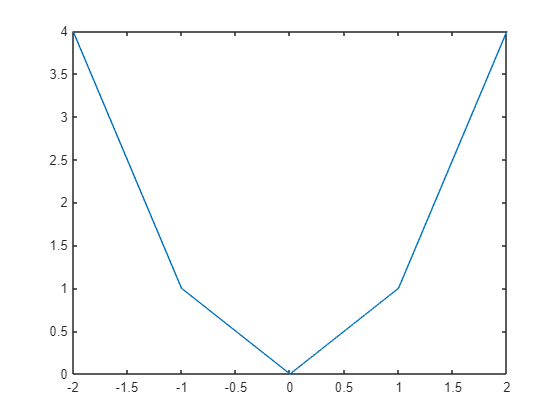

plot(x,y)

b)Aumente o número de ponto de variavel independente x, considerando passando de 0 a 1 e refaça o item anterior

% o 0.1 é o incremento 
x = -2:0.1:2

x =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y = x.^2

y =     4.0000    3.6100    3.2400    2.8900    2.5600    2.2500    1.9600    1.6900    1.4400    1.2100    1.0000    0.8100    0.6400    0.4900    0.3600    0.2500    0.1600    0.0900    0.0400    0.0100         0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000


length(y)

ans = 41

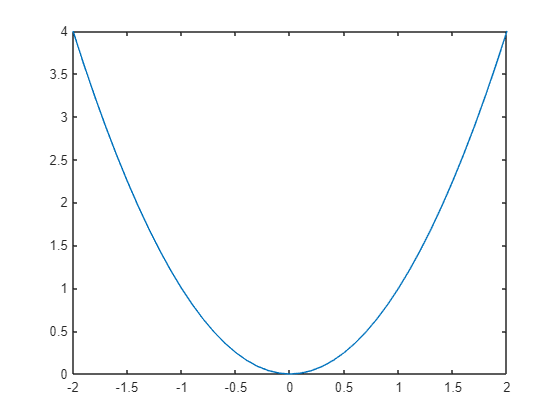

plot(x,y)

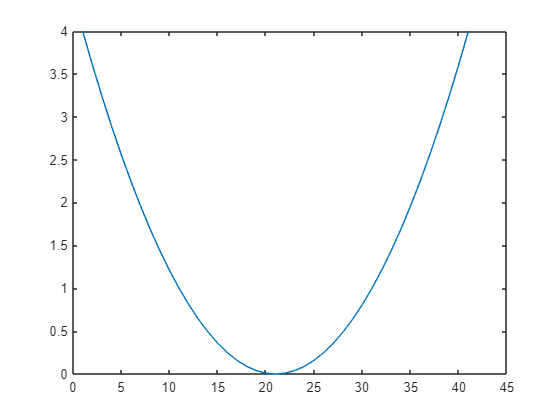

plot(y)

**Comando LInspace e Logspace**

x=0:0.25:1

x =          0    0.2500    0.5000    0.7500    1.0000


% criar um vetor com cinco pontos espaçados.No linspace voce coloca o
% numero de elementos de 1 a 5
x = linspace(0,1,5)

x =          0    0.2500    0.5000    0.7500    1.0000


% espaçamento em logaritimo
logspace(0,1,5)

ans =     1.0000    1.7783    3.1623    5.6234   10.0000


**Plotando várias funções em uma figura**

c)Plote as seguintes funções da mesma figura $y\left(x\right)=x^2 \cos \left(x\right)\ldotp g\left(x\right)=\mathrm{xcos}\left(x\right),f\left(x\right)\;=2^x \mathrm{sen}\left(x\right),0\le x\le 2\pi$considerando 100 pontos.

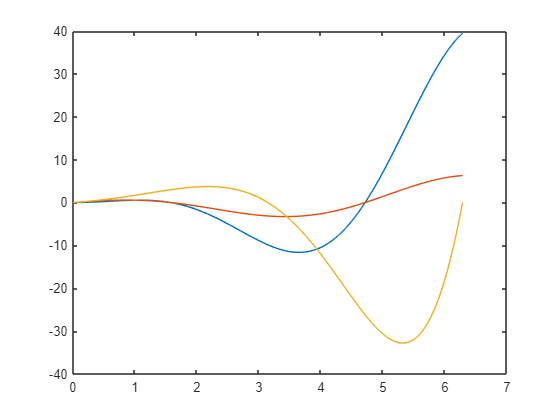

x = linspace(0,2*pi,100);
y = (x.^2).*cos(x);
g = x.*cos(x);
f= (2.^x).*sin(x);
% tem sempre que colocar abscisa e ordenada
plot(x,y,x,g,x,f)

**Configurando opções de plot**

d)plote as funções $y_1 \left(x\right)=\mathrm{asin}\left(x\right)\;e\;y_2 \left(x\right)=\mathrm{acos}\left(x\right)$ com 15 pontos

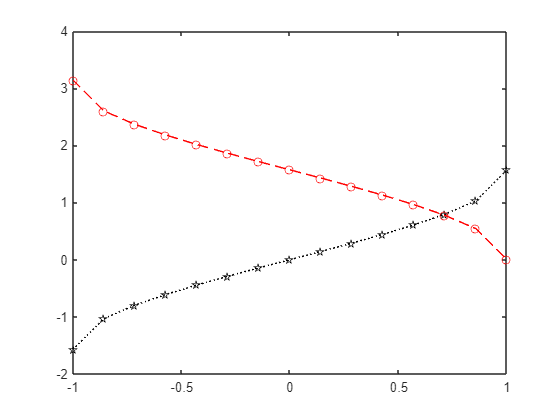

x = linspace(-1,1,15);
y1 = asin(x);
y2 =acos(x);
plot(x,y1,'k:p',x,y2,'r--o')

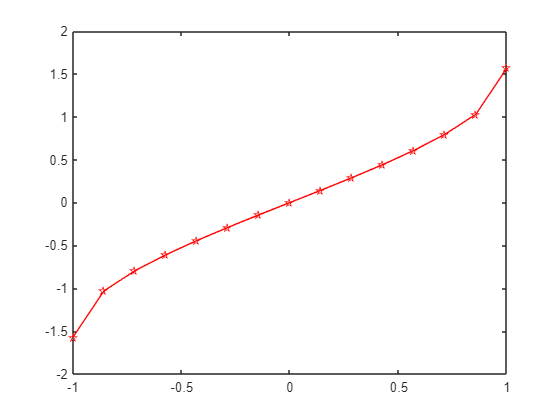

plot(x,y1,"marker","pentagram",'Color',[1 0 0])

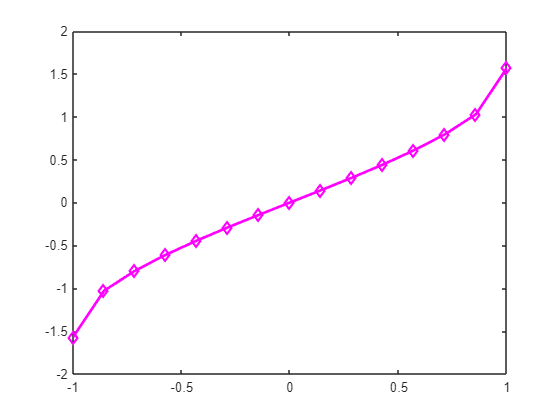

plot(x,y1,'Color',[1 0 1],'LineWidth',2,"Marker","diamond","LineStyle","-")

**Comando Hold**

Comando hold serve para aparecer as duas funções na mesma imagem

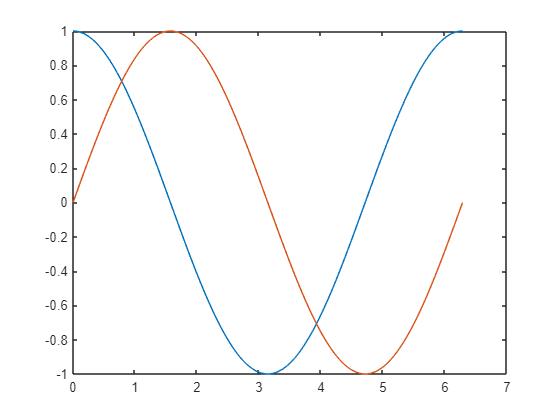

x = linspace(0,2*pi,150);
plot(x,cos(x))
hold on
plot(x,sin(x))

**Formatando uma figura**

grid-title-xlabel-ylabel